# Max_Vogel_CMSDataAnalysis.mlx

This code reads dilepton files from CMS and fits bumps in dilepton mass distributions. The data are available at  [http://opendata.cern.ch/](http://opendata.cern.ch/).

Author: Max Vogel

Date: 10/14/2020

Collaborators: John Podczerwinski, Robert Wheatley, & Jaden Sengkhammee -- helped troubleshoot during lab.

Contributions: Professor Carlsmith for the code template and the CERN lab for collecting this data and making it avaliable!

## Z to two electrons

[Dataset URL](http://opendata.cern.ch/record/306)

### Initialize 

clear;% clear variables
delete(findall(0,'Type','figure'))% close all open figure windows

### Import & Prepare Data

We'll first import the CSV data file

filename='Zee.csv';A=csvread(filename,1,1);nbins=100;
filename ; %drop filename to command window for users benefit

Then we'll create vectors for the energy, momentum components, transverse momentum, (pseudo)rapidity, azimuthal angle, & charge in units of proton charge.

Event=A(:,2);
E1=A(:,3);px1=A(:,4);py1=A(:,5);pz1=A(:,6);pt1=A(:,7);
eta1=A(:,8);phi1=A(:,9);q1=A(:,10);
E2=A(:,11);px2=A(:,12);py2=A(:,13);pz2=A(:,14);pt2=A(:,15);
eta2=A(:,16);phi2=A(:,17);q2=A(:,18);
M=A(:,19); %pair mass supplied by CMS

We can then compute the invariant mass of each lepton

m1= (abs(E1.^2-px1.^2-py1.^2-pz1.^2)).^(1/2);% mass of lepton 1
m2= (abs(E2.^2-px2.^2-py2.^2-pz2.^2)).^(1/2);% mass of lepton 2
m3=(abs((E1+E2).^2-(px1+px2).^2-(py1+py2).^2-(pz1+pz2).^2)).^(1/2);

...and then create the vector `Nevents` for the number of entries per bin created by the `histogram` command along with `edges` which is a vector of bin edges.

[Nevents,edges] = histcounts(m3,nbins);

With this data, we can create `err` containing statistical standard error in each bin equal to the square root of the number of events in that bin ([Poisson statistics](https://en.wikipedia.org/wiki/Poisson_distribution))

err=Nevents.^(1/2);

Since `edges` starts at lower edge of first bin and ends at upper edge of last bin, we'll create the `mass `equal the vector of bin centers by eliminating last edge and adding a half bin size to each element.

mass=edges(1:end-1);
mass=mass +(edges(2)-edges(1))/2;

### Mass distribution fit

We'll use the [Relativistic Breit–Wigner distribution](https://en.wikipedia.org/wiki/Relativistic_Breit%E2%80%93Wigner_distribution):  $\frac{k}{(m^2-m_Z^2)^2 + m_Z^2 \cdot \Gamma_Z^2 }$ where $m_z$ is the Z-boson mass treated as a parameter, $\Gamma_Z$is the width of the Z-boson mass, and $k$ is a normalization constant.

createFitVogelZee(mass, Nevents, err)

ans =      General model:
     ans(x) = k * 1/((x^2 -  mz^2)^2 + mz^2 * wz^2)
     Coefficients (with 95% confidence bounds):
       k =   3.302e+07  (1.209e+07, 5.395e+07)
       mz =       88.72  (87.94, 89.5)
       wz =      -6.512  (-9.019, -4.006)

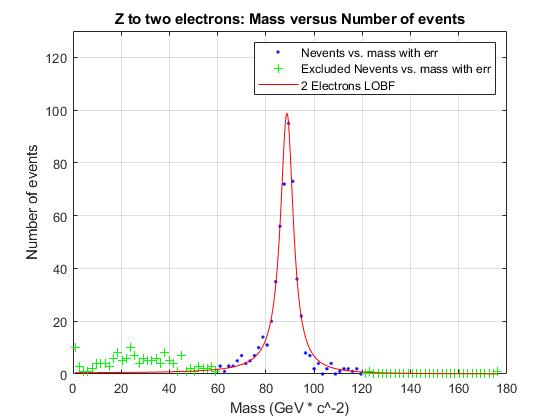

title("Z to two electrons: Mass versus Number of events")
ylabel("Number of events")
xlabel("Mass (GeV * c^-2)")
ylim([0 130]); % so table doesn't obstruct view

For this fit, $m_z$ was 88.72 while the true value is 91.1876 GeV*c^-2, $\Gamma_Z$was 6.512 while the true is 2.4952 GeV*c^-2, and $k$ was 3.302*10^7 (which was the constant.) All of the true values can be found on the [PDG's site](https://pdg.lbl.gov/2020/listings/rpp2020-list-z-boson.pdf). These descripancies fall outside of two standard deviations of their resepctive measurements. The  $m_z$ value controls the center of the "spike" in the graph, so when collecting the data perhaps mass was over-estimated when being measured. Morevoer, the line of best fit only considers the lines values with a mass greater than 60 and less than 120 so perhaps those bounds were inaccurate and morphed the  $\Gamma_Z$ to be much higher than it should have been.

## Z to two muons

[Dataset URL](http://opendata.cern.ch/record/307)

### Initialize 

clear;% clear variables
delete(findall(0,'Type','figure'))% close all open figure windows

### Import & Prepare Data

We'll first import the CSV data file

filename='Zmumu.csv';A=csvread(filename,1,1);nbins=100;
filename ; %drop filename to command window for users benefit

Then we'll create vectors for the energy, momentum components, transverse momentum, (pseudo)rapidity, azimuthal angle, & charge in units of proton charge.

Event=A(:,2);
E1=A(:,3);px1=A(:,4);py1=A(:,5);pz1=A(:,6);pt1=A(:,7);
eta1=A(:,8);phi1=A(:,9);q1=A(:,10);
E2=A(:,11);px2=A(:,12);py2=A(:,13);pz2=A(:,14);pt2=A(:,15);
eta2=A(:,16);phi2=A(:,17);q2=A(:,18);
M=A(:,19); %pair mass supplied by CMS

We can then compute the invariant mass of each lepton

m1= (abs(E1.^2-px1.^2-py1.^2-pz1.^2)).^(1/2);% mass of lepton 1
m2= (abs(E2.^2-px2.^2-py2.^2-pz2.^2)).^(1/2);% mass of lepton 2
m3=(abs((E1+E2).^2-(px1+px2).^2-(py1+py2).^2-(pz1+pz2).^2)).^(1/2);

...and then create the vector `Nevents` for the number of entries per bin created by the `histogram` command along with `edges` which is a vector of bin edges.

[Nevents,edges] = histcounts(m3,nbins);

With this data, we can create `err` containing statistical standard error in each bin equal to the square root of the number of events in that bin ([Poisson statistics](https://en.wikipedia.org/wiki/Poisson_distribution))

err=Nevents.^(1/2);

Since `edges` starts at lower edge of first bin and ends at upper edge of last bin, we'll create the `mass `equal the vector of bin centers by eliminating last edge and adding a half bin size to each element.

mass=edges(1:end-1);
mass=mass +(edges(2)-edges(1))/2;

### Mass distribution fit

We'll use the [Relativistic Breit–Wigner distribution](https://en.wikipedia.org/wiki/Relativistic_Breit%E2%80%93Wigner_distribution):  $\frac{k}{(m^2-m_Z^2)^2 + m_Z^2 \cdot \Gamma_Z^2 }$ where $m_z$ is the Z-boson mass treated as a parameter, $\Gamma_Z$is the width of the Z-boson mass, and $k$ is a normalization constant.

createFitVogelZmumu(mass, Nevents, err)

ans =      General model:
     ans(x) = k * 1/((x^2 -  mz^2)^2 + mz^2 * wz^2)
     Coefficients (with 95% confidence bounds):
       k =       1e+08  (fixed at bound)
       mz =        90.9  (90.83, 90.96)
       wz =       4.982  (4.935, 5.029)

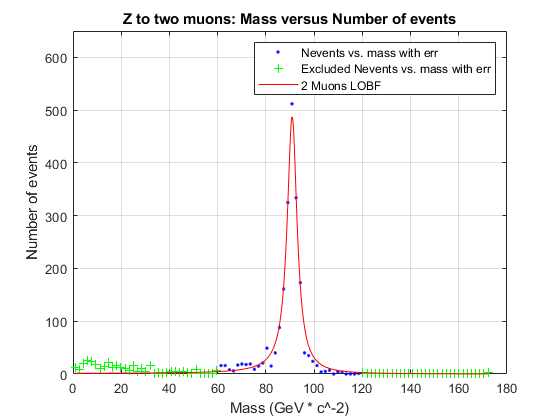

title("Z to two muons: Mass versus Number of events")
ylabel("Number of events")
xlabel("Mass (GeV * c^-2)")
ylim([0 650]); % so table doesn't obstruct view

For this fit, $m_z$ was 90.9 while the true value is 91.1876 GeV*c^-2, $\Gamma_Z$was 4.982 while the true is 2.4952 GeV*c^-2, and $k$ was 1*10^8 (which was the constant.) All of the true values can be found on the [PDG's site](https://pdg.lbl.gov/2020/listings/rpp2020-list-z-boson.pdf). Again, these descripancies fall outside of two standard deviations of their resepctive measurements. Because the $k$ value (which is responsible for the amplitute) was fixed/limited, it could have caused the $\Gamma_Z$ value (which also affects the amplitude as well as width of the spike) to be incorrectly estimated.